# Process the intensity data from Idler

Theta = (0,2) degrees.

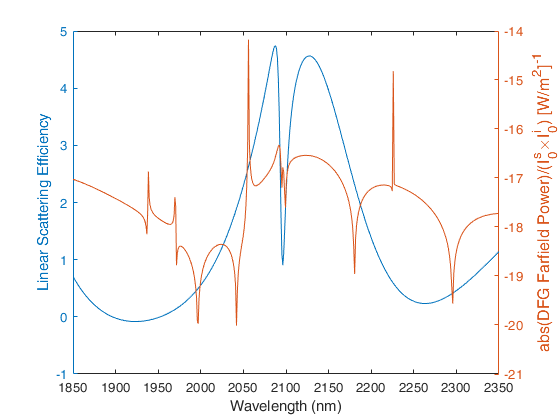

ans = 1.4407

FT_num = 5

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed\processed');

fig = figure;

for job = "paris_2_2"
    eval(job);
    load([options.output_dir_final 'derived_values.mat']);
    load([options.output_dir_final 'cut_plane\sum_fft.mat']);
    
    extra_options = matthew_extra_options(options);
    
    wlengths = 299792458./derived_values.signal.freq;
    denom = derived_values.parameters.I0*derived_values.parameters.I0_i;
    
    log10(max(derived_values.sfg.scat3_eff)/derived_values.sfg.scat3_eff(1))
    % {
    yyaxis left;
    plot(wlengths, derived_values.signal.scat_eff); % scat3_eff
    %plot(derived_values.signal.scat_eff); % scat3_eff
    hold on
    ylabel('Linear Scattering Efficiency');
    xlabel('Wavelength (nm)');
    yyaxis right;
    %}
    %plot(wlengths, log10(derived_values.sfg.scat3_eff), '-'); % int_Isfg
    %plot(log10(derived_values.sfg.scat3_eff)); % int_Isfg
    %leg_scat3 = legend({'Signal','log_{10}(SFG)'});
    %leg_scat3 = legend({'\phi=0','\phi=90^o'});
    %leg_scat3.Location = 'southeast';
    %title(strcat(job, ", phi = ", phi_str), 'Interpreter', 'none');
    %saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_phi_", phi_str), 'png');
    %axis([2014 2016 -12 -6]);

    [FTx, FTy, FTz,FThx, FThy, FThz, FTpoynting] = ...
        matthew_get_fft_of_cut_plane_all_freqs(sum_fft, "FF", "down");
    
    FT_num = 5%1:5
    switch FT_num
        case 1
            FTxyz = FTx;
            FThxyz = FThx;
        case 2
            FTxyz = FTy;
            FThxyz = FThy;
        case 3
            FTxyz = FTz;
            FThxyz = FThz;
        case 4
            FTxyz = abs(FTx).^2 + abs(FTy).^2;
            FThxyz = abs(FThx).^2 + abs(FThy).^2;
        otherwise
            FTxyz = FTpoynting;
    end
        plot(wlengths, log10(abs(FTxyz(:,2,2))/denom));
        ylabel("abs(DFG Farfield Power)/(I_0^s\timesI_0^i) [W/m^2]^{-1}", 'FontSize', 12)   
end